clear; clc; close all;
set(groot, 'defaultFigureRenderer', 'painters');


[y1, fs] = audioread("C:\Users\18237\Desktop\C_01_02(1).wav");
y1 = y1(:)';

vocoder_input = y1;

L = length(vocoder_input);
t = (0:L-1) / fs;
f = fs * (0:floor(L/2)) / L;



N = 4;
f_min = 200;
f_max = 7000;
LPF_cut_freq = 50;

[b_lpf, a_lpf] = butter(2, LPF_cut_freq / (fs/2));



pass_band_lower = f_min : (f_max - f_min) / N : f_max - (f_max - f_min) / N;
pass_band_upper = f_min + (f_max - f_min) / N : (f_max - f_min) / N : f_max;
center_freq = (pass_band_lower + pass_band_upper) / 2;

disp('Band division result:');

Band division result:


band_table = table((1:N)', pass_band_lower', pass_band_upper', center_freq', ...
    'VariableNames', {'Band', 'Lower_Hz', 'Upper_Hz', 'Center_Hz'});
disp(band_table);

    Band    Lower_Hz    Upper_Hz    Center_Hz
    ____    ________    ________    _________

     1         200        1900        1050   
     2        1900        3600        2750   
     3        3600        5300        4450   
     4        5300        7000        6150   



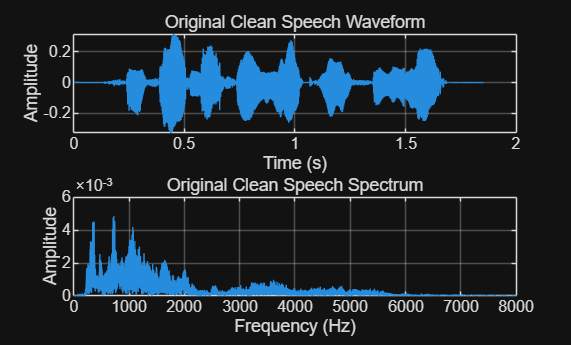



figure('Name', 'Original Clean Speech');

subplot(2,1,1);
plot(t, vocoder_input);
title('Original Clean Speech Waveform');
xlabel('Time (s)');
ylabel('Amplitude');
grid on;

subplot(2,1,2);
Y_fft = fft(vocoder_input);
P = abs(Y_fft / L);
P_single = P(1:floor(L/2)+1);
P_single(2:end-1) = 2 * P_single(2:end-1);

plot(f, P_single);
title('Original Clean Speech Spectrum');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0, 8000]);
grid on;

saveas(gcf, 'Additional_Task2_original_clean_speech.png');

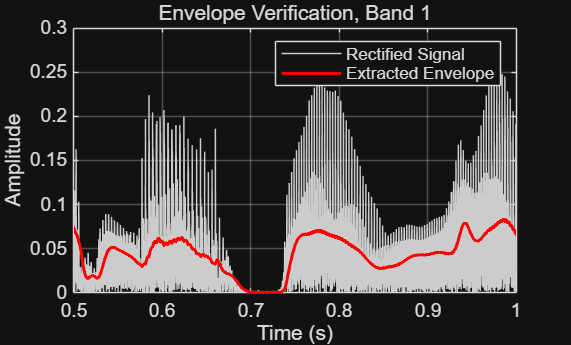

Center-Frequency Sine: input energy = 87.0316, before normalization = 57.4992, after normalization = 87.0316


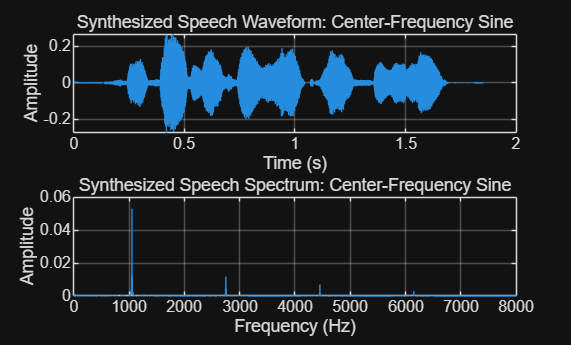

Lower-Bound Sine: input energy = 87.0316, before normalization = 57.4684, after normalization = 87.0316


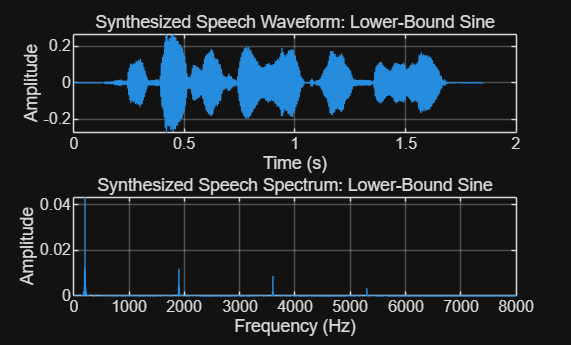

Upper-Bound Sine: input energy = 87.0316, before normalization = 57.5020, after normalization = 87.0316


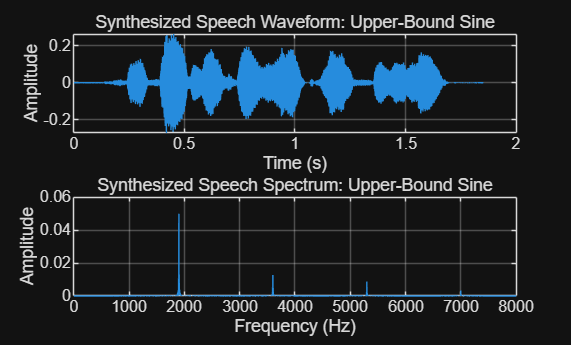

Band-Limited Noise: input energy = 87.0316, before normalization = 57.2389, after normalization = 87.0316


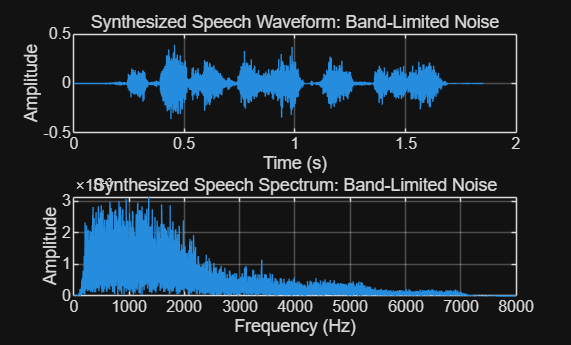




carrier_types = {'center_sine', 'lower_sine', 'upper_sine', 'band_limited_noise'};
carrier_labels = {'Center-Frequency Sine', 'Lower-Bound Sine', 'Upper-Bound Sine', 'Band-Limited Noise'};

all_outputs = cell(length(carrier_types), 1);
all_output_names = cell(length(carrier_types), 1);
energy_result = zeros(length(carrier_types), 3);

rng(0);



for c = 1:length(carrier_types)

    carrier_type = carrier_types{c};
    carrier_label = carrier_labels{c};

    y_sum = zeros(1, L);

    for i = 1:N

        Wn = [pass_band_lower(i), pass_band_upper(i)] / (fs/2);

        [B_bp, A_bp] = butter(4, Wn, 'bandpass');

        y_band = filter(B_bp, A_bp, vocoder_input);

        y_rectified = abs(y_band);

        y_envelope = filter(b_lpf, a_lpf, y_rectified);

        if i == 1 && c == 1
            figure('Name', 'Envelope Verification');
            plot(t, y_rectified, 'Color', [0.8 0.8 0.8]);
            hold on;
            plot(t, y_envelope, 'r', 'LineWidth', 1.5);
            hold off;
            title('Envelope Verification, Band 1');
            xlabel('Time (s)');
            ylabel('Amplitude');
            legend('Rectified Signal', 'Extracted Envelope');
            xlim([0.5, 1.0]);
            grid on;
            saveas(gcf, 'Additional_Task2_envelope_verification.png');
        end

        carrier = generate_carrier(carrier_type, center_freq(i), ...
            pass_band_lower(i), pass_band_upper(i), t, fs, L);

        carrier = carrier / (sqrt(mean(carrier.^2)) + eps);

        y_modulated = y_envelope .* carrier;

        y_sum = y_sum + y_modulated;

    end

    e_input = sum(vocoder_input.^2);
    e_synth_before = sum(y_sum.^2);

    y_synth = y_sum * sqrt(e_input / (e_synth_before + eps));

    e_synth_after = sum(y_synth.^2);

    all_outputs{c} = y_synth;
    all_output_names{c} = carrier_type;

    energy_result(c, :) = [e_input, e_synth_before, e_synth_after];

    filename = sprintf('Additional_Task2_carrier_%s_N%d_LPF%dHz.wav', ...
        carrier_type, N, LPF_cut_freq);

    audiowrite(filename, y_synth, fs);

    fprintf('%s: input energy = %.4f, before normalization = %.4f, after normalization = %.4f\n', ...
        carrier_label, e_input, e_synth_before, e_synth_after);

    figure('Name', ['Synthesized Signal - ', carrier_label]);

    subplot(2,1,1);
    plot(t, y_synth);
    title(['Synthesized Speech Waveform: ', carrier_label]);
    xlabel('Time (s)');
    ylabel('Amplitude');
    grid on;

    subplot(2,1,2);
    Y_fft = fft(y_synth);
    P = abs(Y_fft / L);
    P_single = P(1:floor(L/2)+1);
    P_single(2:end-1) = 2 * P_single(2:end-1);

    plot(f, P_single);
    title(['Synthesized Speech Spectrum: ', carrier_label]);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');
    xlim([0, 8000]);
    grid on;

    saveas(gcf, sprintf('Additional_Task2_carrier_%s_result.png', carrier_type));

end

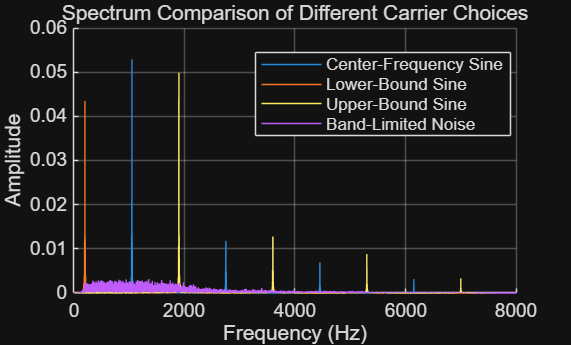



figure('Name', 'Carrier Selection Spectrum Comparison');
hold on;

for c = 1:length(carrier_types)

    y_synth = all_outputs{c};

    Y_fft = fft(y_synth);
    P = abs(Y_fft / L);
    P_single = P(1:floor(L/2)+1);
    P_single(2:end-1) = 2 * P_single(2:end-1);

    plot(f, P_single);

end

hold off;
title('Spectrum Comparison of Different Carrier Choices');
xlabel('Frequency (Hz)');
ylabel('Amplitude');
xlim([0, 8000]);
legend(carrier_labels, 'Location', 'best');
grid on;

saveas(gcf, 'Additional_Task2_carrier_spectrum_comparison.png');

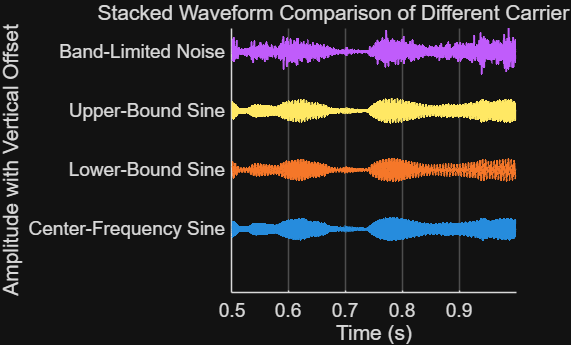




t_start = 0.5;
t_end = 1.0;

idx = find(t >= t_start & t <= t_end);


max_plot_points = 4000;
plot_step = max(1, floor(length(idx) / max_plot_points));
idx_plot = idx(1:plot_step:end);


max_amp = 0;
for c = 1:length(carrier_types)
    max_amp = max(max_amp, max(abs(all_outputs{c}(idx_plot))));
end

offset_step = 2.5 * (max_amp + eps);

figure('Name', 'Carrier Selection Waveform Comparison', 'Renderer', 'painters');
hold on;

for c = 1:length(carrier_types)
    y_plot = all_outputs{c}(idx_plot) + (c - 1) * offset_step;
    plot(t(idx_plot), y_plot, 'LineWidth', 1.0);
end

hold off;
title('Stacked Waveform Comparison of Different Carrier Choices');
xlabel('Time (s)');
ylabel('Amplitude with Vertical Offset');
yticks((0:length(carrier_labels)-1) * offset_step);
yticklabels(carrier_labels);
grid on;

exportgraphics(gcf, 'Additional_Task2_carrier_waveform_comparison.png', 'Resolution', 300);

drawnow;



energy_table = table(carrier_labels', energy_result(:,1), energy_result(:,2), energy_result(:,3), ...
    'VariableNames', {'Carrier_Type', 'Input_Energy', 'Energy_Before_Normalization', 'Energy_After_Normalization'});

disp('Energy verification result:');

Energy verification result:


disp(energy_table);

          Carrier_Type           Input_Energy    Energy_Before_Normalization    Energy_After_Normalization
    _________________________    ____________    ___________________________    __________________________

    {'Center-Frequency Sine'}       87.032                 57.499                         87.032          
    {'Lower-Bound Sine'     }       87.032                 57.468                         87.032          
    {'Upper-Bound Sine'     }       87.032                 57.502                         87.032          
    {'Band-Limited Noise'   }       87.032                 57.239                         87.032          




writetable(energy_table, 'Additional_Task2_energy_verification.csv');
writetable(band_table, 'Additional_Task2_band_table.csv');

disp('Additional Task 2 finished.');

Additional Task 2 finished.





function carrier = generate_carrier(carrier_type, fc, f_low, f_high, t, fs, L)

    switch carrier_type

        case 'center_sine'
            carrier = sin(2 * pi * fc * t);

        case 'lower_sine'
            carrier = sin(2 * pi * f_low * t);

        case 'upper_sine'
            carrier = sin(2 * pi * f_high * t);

        case 'band_limited_noise'
            raw_noise = randn(1, L);
            Wn = [f_low, f_high] / (fs/2);
            [B_noise, A_noise] = butter(4, Wn, 'bandpass');
            carrier = filter(B_noise, A_noise, raw_noise);

        otherwise
            error('Unknown carrier type: %s', carrier_type);

    end

end
